## The purpose of this tutorial is to demonstrate the intermediate transfer functions composing the AWG.

clear; clc

addpath(genpath('.'));

Create AWG definition for a 100GHz demultiplexer on SOI

model = awg.AWG("N",220,"g",0.5,"d",1.2);

lambda = model.lambda_c + .00;
modetype = 'gaussian';
input = 0;

Generate input field distribution

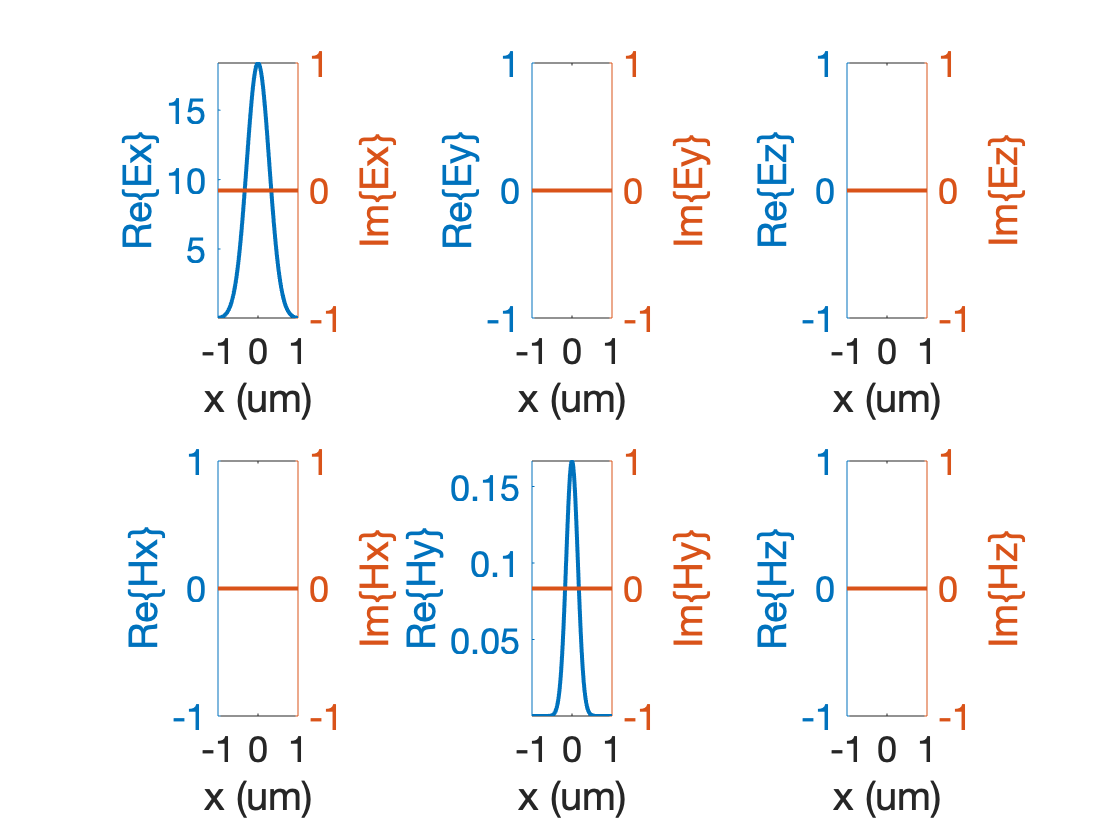

x = linspace(-model.wi*5, +model.wi*5, 500);
a = 3;
b = a - .1;
u = exp(-((x - b)/a).^2) + exp(-((x + b)/a).^2);
u = rectf(x/a);
F = awg.Field(x, u).normalize();

F1 = awg.iw(model, lambda, 0, 'ModeType', modetype, 'Points', 100);

awg.plotfield(F1);

Propagate input field accross free propagation region

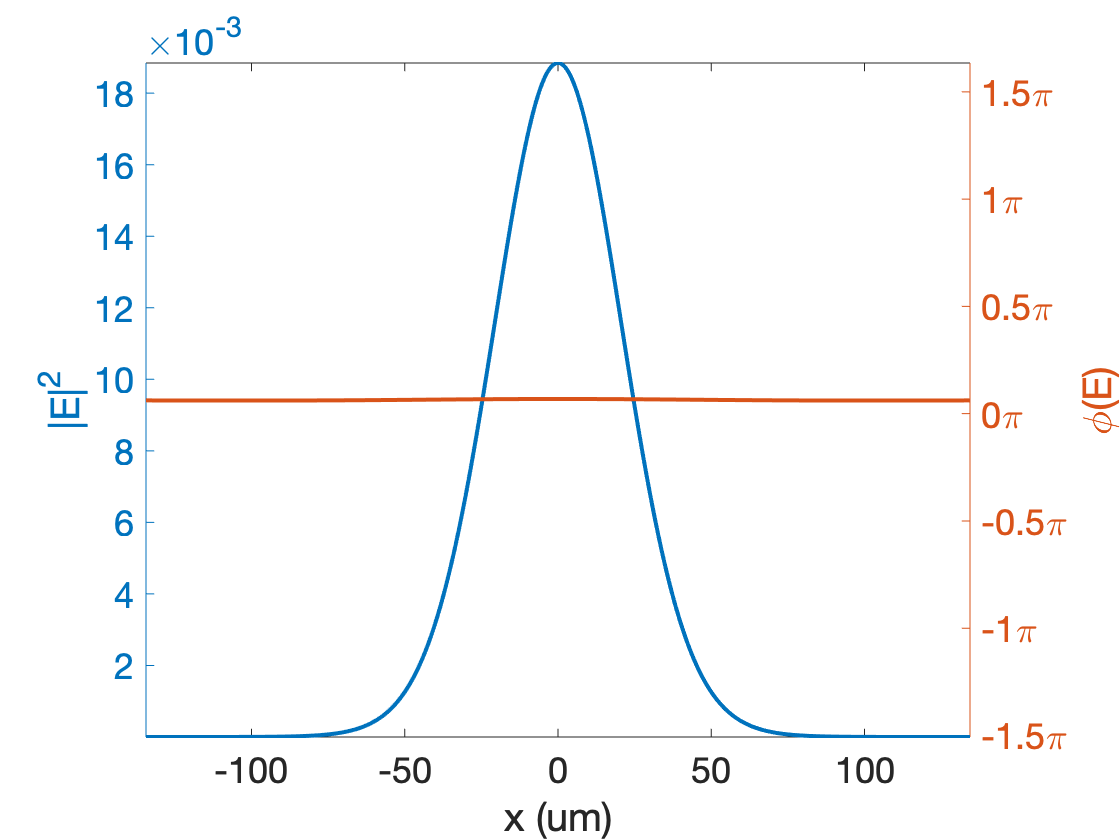

F2 = awg.fpr1(model, lambda, F1, 'Input', input, 'Points', 1500);

awg.plotfield(F2, 'PlotPhase', 1, 'UnwrapPhase', 1, 'NormalizePhase', 1);

Couple diffracted field to array apertures and propagate modes

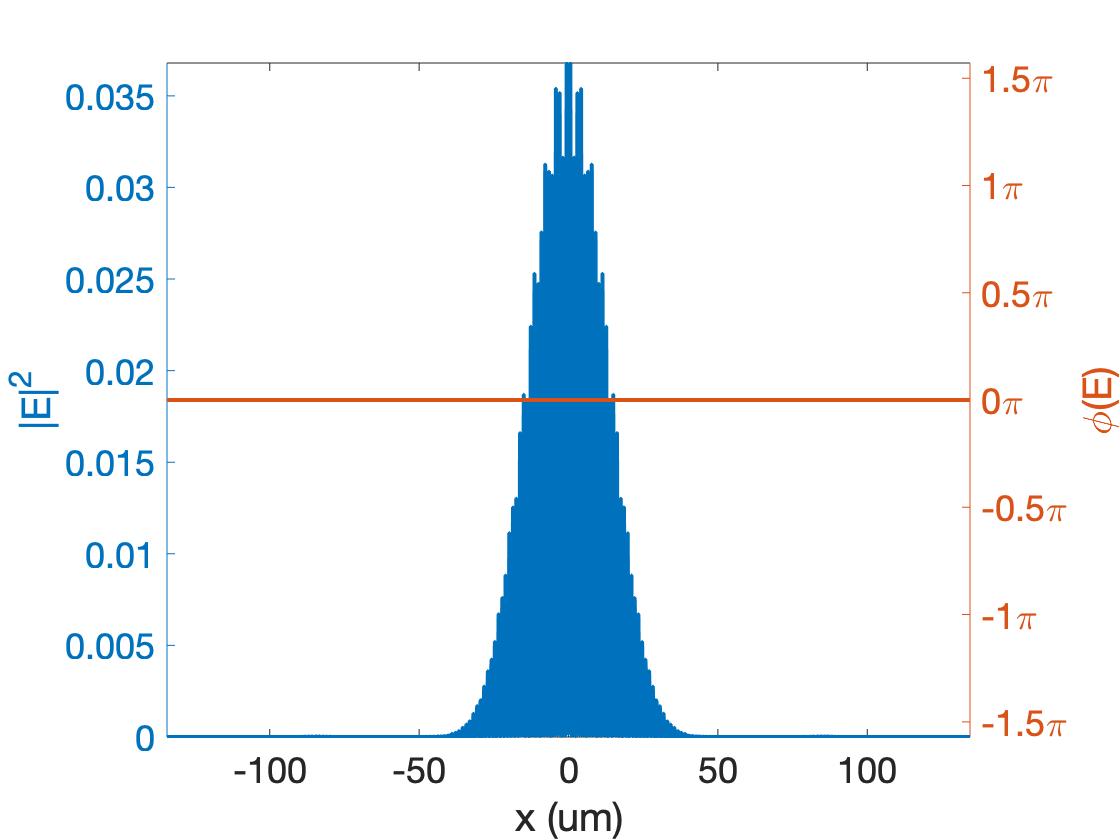

F3 = awg.aw(model, lambda, F2, 'ModeType', modetype);

awg.plotfield(F3, 'PlotPhase', 1, 'UnwrapPhase', 1, 'NormalizePhase', 1);

Propagate array field accross free propagation region

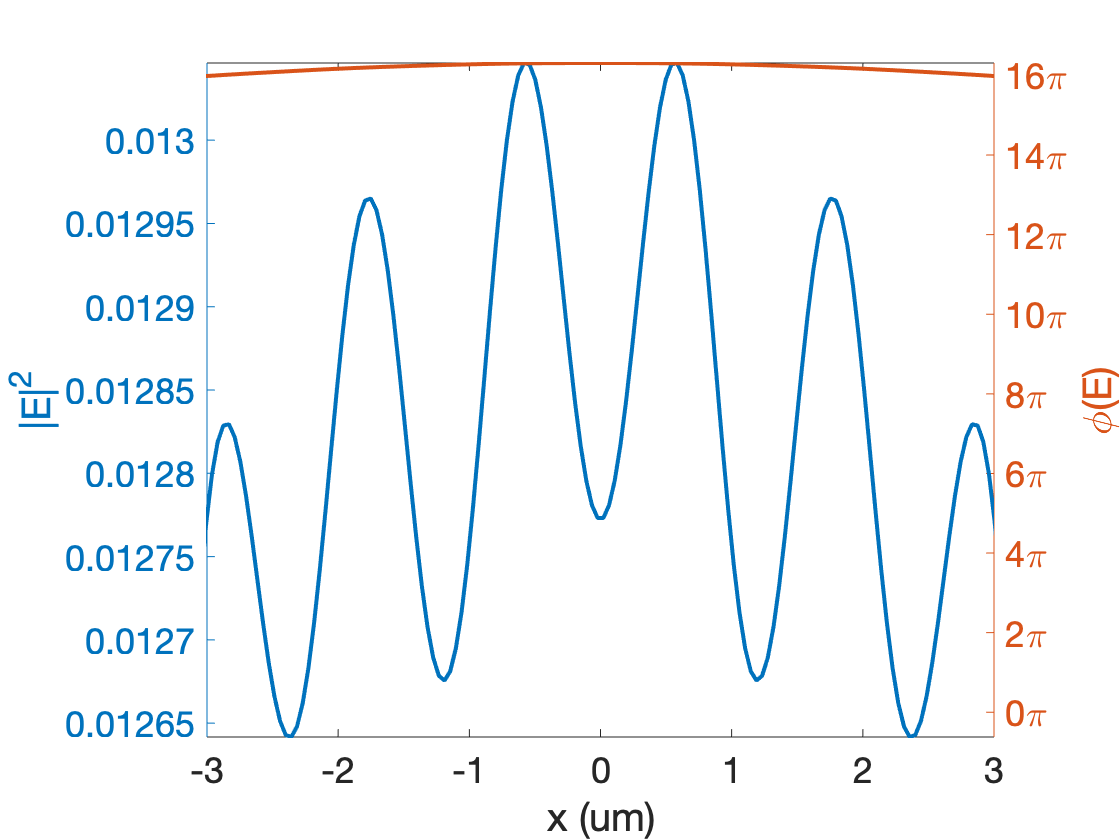

F4 = awg.fpr2(model, lambda, F3, 'Points', 1000);

awg.plotfield(F4, 'PlotPhase', 1, 'UnwrapPhase', 1, 'NormalizePhase', 1);
xlim([-3,3])

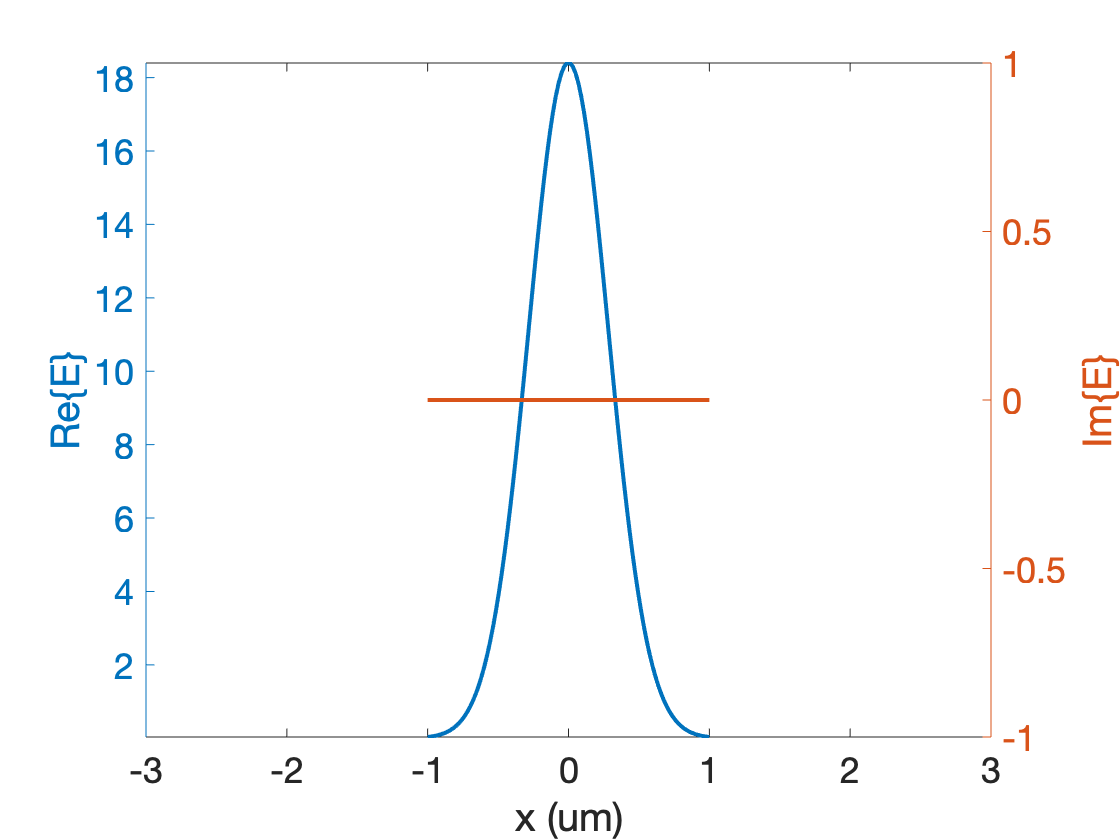

awg.plotfield(F1.x,F1.Ex)

xlim([-3,3])

Couple diffracted field to output apertures

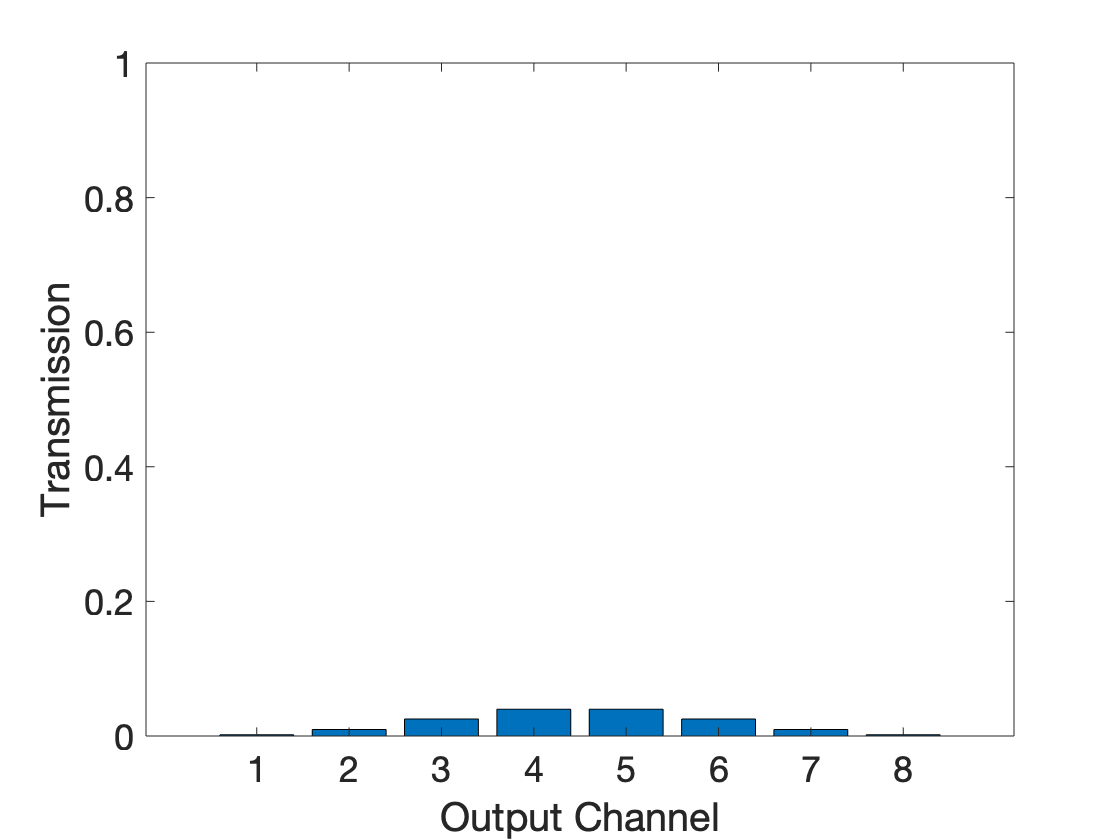

T = awg.ow(model, lambda, F4, 'ModeType', modetype);

figure
bar(T)
ylim([0,1])
xlabel('Output Channel')
ylabel('Transmission')
set(gca,'FontSize',18)